**Primer Orden**

clc
clear variables
close all

Ts = 0.1; %seg
num = 1;
den = [1 1];
sys = tf(num,den)

sys =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties



Gs=c2d(sys,Ts,'zoh')

Gs =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


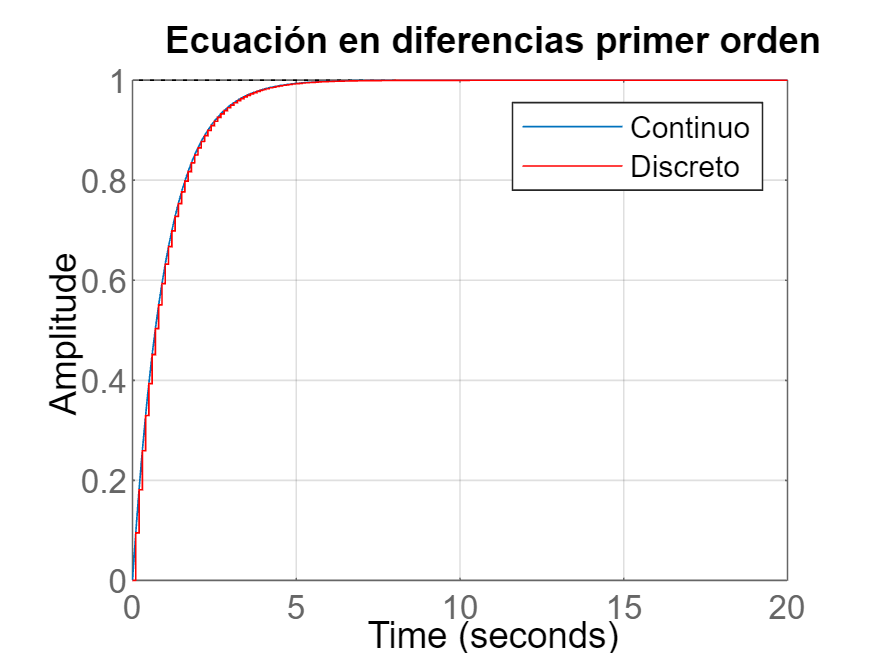

tsim = 20;
step(sys,tsim)
hold on

ukm1 = 0;
xkm1 = 0;
k=0:Ts:tsim;
for i=1:length(k)

    xk(i)=ukm1*0.09516+xkm1*0.9048;
    xkm1=xk(i);
    ukm1=1;
    
end
stairs(k,xk,'r')
title('Ecuación en diferencias primer orden')
legend('Continuo','Discreto')
grid on
hold off